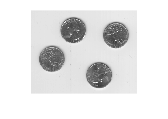

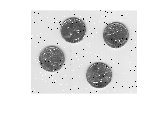

I = imread('eight.tif');

J = imnoise(I,'salt & pepper', 0.02);

K = imnoise(J,'gaussian',0,0.005);

figure, imshow(I), figure, imshow(J)

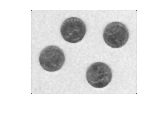


K = medfilt2(K,[5 5]);

K = wiener2(K,[3 3]);

figure, imshow(K)